# Create Simulink Environment and Train Agent

This example shows how to convert the PI controller in `watertank.slx` to a reinforcement learning deep deterministic policy gradient (DDPG) agent. For an example that trains a DDPG agent in MATLAB®, see [Train DDPG Agent to Balance Double Integrator Environment](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

## Water Tank Model

The original model for this example is the water tank model. The goal is to control the level of the water in the tank. For more information about the water tank model, see [watertank Simulink Model](docid:slcontrol_gs#bsp4o3g).

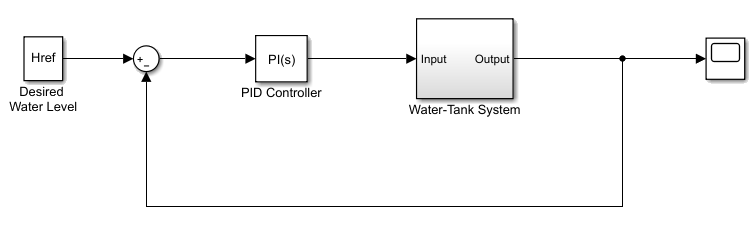

Modify the original model, making the following changes:

- Delete the PID Controller.

- Insert the RL Agent block.

- Connect the observation vector ${\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & h
\end{array}\right\rbrack }^{T\;}$ where $h$ is the height of the tank, $e=r-h$, and $r$ is the reference height.

- Set up the reward $\textrm{reward}=10\left(\left|e\right|<0\ldotp 1\right)-1\left(\left|e\right|\ge 0\ldotp 1\right)-100\left(h\le 0\left|\right|h\ge 20\right)$.

- Set up terminate signal if $h\le 0\left|\right|h\ge 20$.

The resulting model is `rlwatertank.slx`. For more information on this model and the changes, see [Create Simulink Environment for Reinforcement Learning](docid:rl_ug#mw_0e8060ca-2e7a-4d41-90d1-3bf4aeb76099).

parameter

ans =
 
     1.77 s
  -------------
  s^3 - 19.08 s
 
연속시간 전달 함수입니다.


ans =
 
     1.156 s
  -------------
  s^3 + 12.46 s
 
연속시간 전달 함수입니다.



open_system('test')

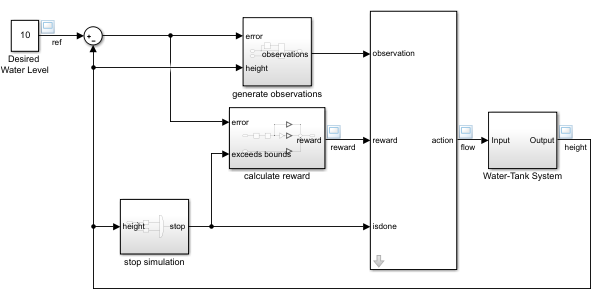

## Create Environment Interface

Creating an environment model includes defining the following:

- Action and observation signals that the agent uses to interact with the environment. For more information see [rlNumericSpec](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [rlFiniteSetSpec](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

- Reward signal that the agent uses to measure its success. For more information, see [Define Reward Signals](docid:rl_ug#mw_1fe437df-5904-43dc-8b75-1e25bb9ae3ff).

Define the observation and action data specifications, `obsInfo` and `actInfo`, respectively.

obsInfo = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf -90]',...
    'UpperLimit',[ inf  inf 90]');
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error, error, and measured height';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([1 1]);
actInfo.Name = 'force';
numActions = actInfo.Dimension(1);

Build the environment interface object.

env = rlSimulinkEnv('test','test/RL Agent',...
    obsInfo,actInfo);

Set a custom reset function that randomizes the reference values for the model.

env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds

Ts = 0.025; % Agent sample time
Tf = 10;    % Simulation end time

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(25,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1],'Normalization','none','Name','Action')
    fullyConnectedLayer(25,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

View the critic network configuration.

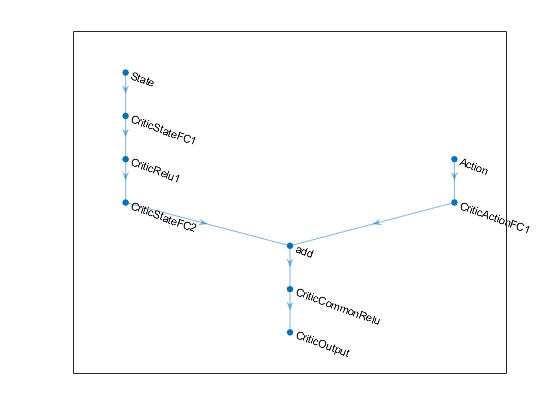

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOpts = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [`rlRepresentation`](docid:rl_ref#mw_453a7f45-3761-4387-9e1d-4c90ed8b5b57).

critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

A DDPG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Construct the actor in a similar manner as the critic. 

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('Name','actorTanh')
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

actor = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

To create the DDPG agent, first specify the DDPG agent options using [rlDDPGAgentOptions](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Then, create the DDPG agent using the specified actor representation, critic representation, and agent options. For more information, see [rlDDPGAgent](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOpts);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `5000` episodes, with each episode lasting at most 2`00` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option).

- Stop training when the agent receives an average cumulative reward greater than 800 over twenty consecutive episodes. At this point, the agent can controls the level of water in a tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',800);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('WaterTankDDPG.mat','agent')
end

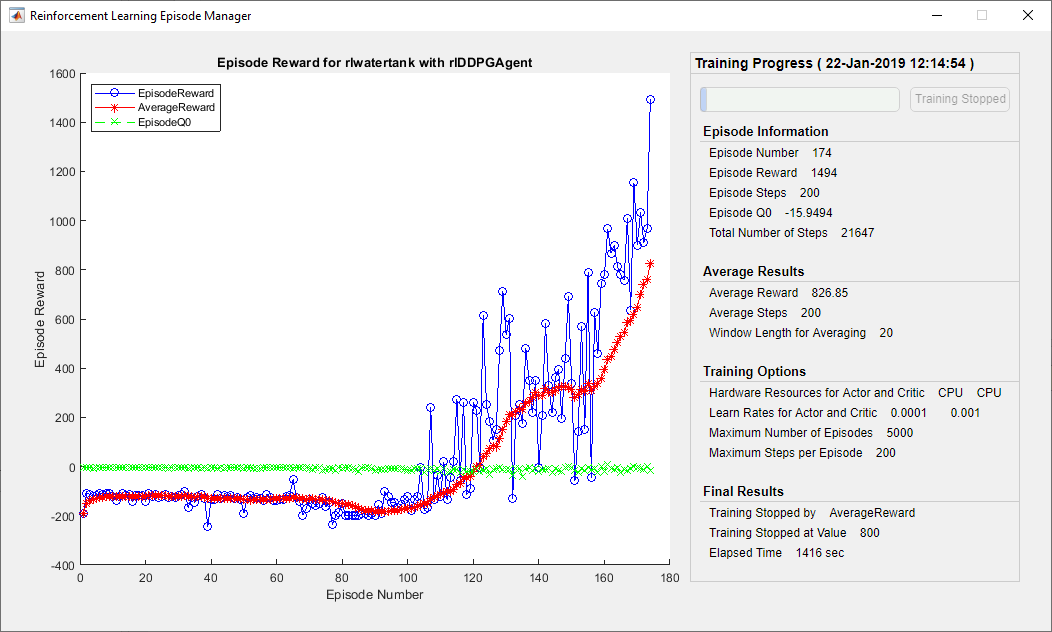

## Validate Trained Agent

Validate the learned agent against the model by simulation.

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
experiences = sim(env,agent,simOpts);

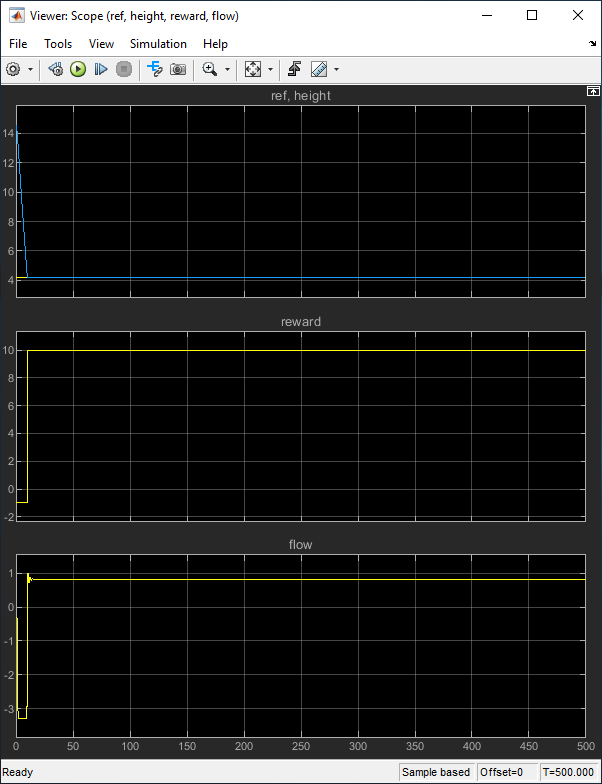

## Local Function

function in = localResetFcn(in)

%initialize ref

a = randn;
% while abs(a)>=1.5708
%     a = randn;
% end

in = setBlockParameter(in, 'test/ref', 'Value', num2str(a));

% initialize inclination
% in = setBlockParameter(in, 'test/Robot System/H', 'InitialCondition', '0');

% initialize torque

end

*Copyright 2019 The MathWorks, Inc.*